**Let's assume y = 0.5e^(0.1x) + 2.    Let's plot this function from x = 0 to 40**

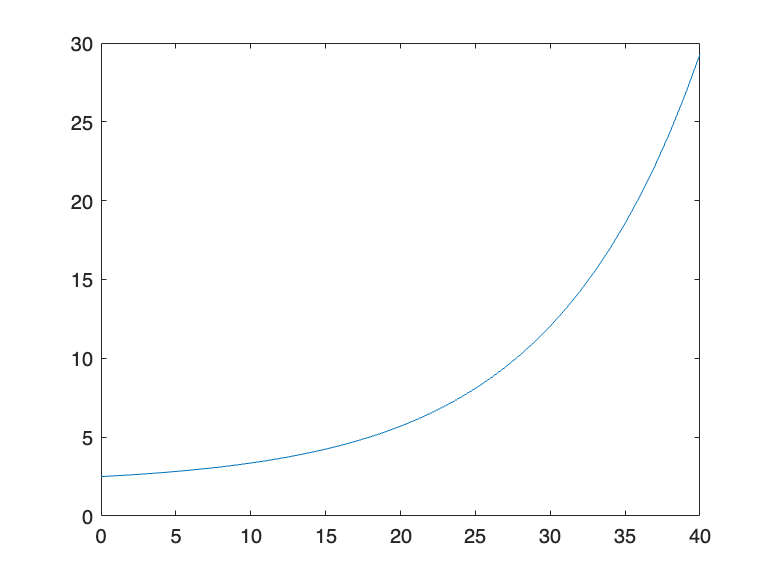

xx = 0:1:40;
yy = 0.5 * exp(0.1 * xx) + 2;
% plot(xx, yy, '-')

**Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use linear interpolation (a first-order Lagrange polynomial) to predict the unknown function**

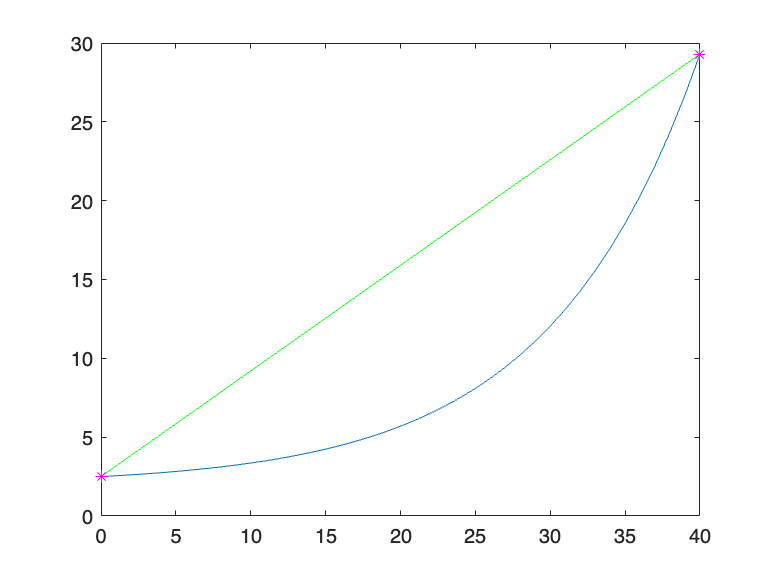

x = linspace(0, 40, 2)';
y = 0.5 * exp(0.1 * x) + 2;


xx = 0:1:40;
yy1_lagrange = Lagrange(x, y, xx);

plot(xx, yy, '-')
hold on
plot(xx, yy1_lagrange, 'g-',x , y, 'm*')
hold off

**Now assume that we only know 3 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a second-order Newton polynomial) to predict the unknown function**

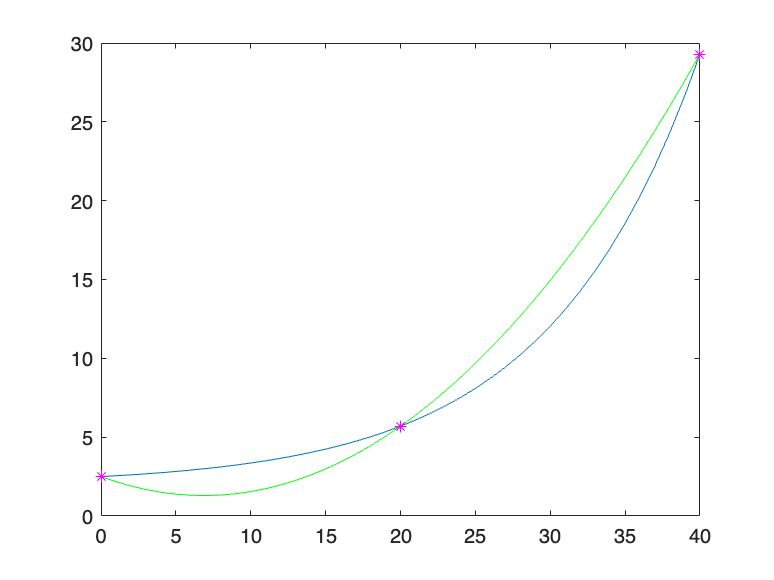

x = linspace(0, 40, 3)';
y = 0.5 * exp(0.1 * x) + 2;


xx = 0:1:40;
yy2_lagrange = Lagrange(x, y, xx);

plot(xx, yy, '-')
hold on
plot(xx, yy2_lagrange, 'g-',x , y, 'm*')
hold off

**Now assume that we only know 4 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a 3th-order Newton polynomial) to predict the unknown function**

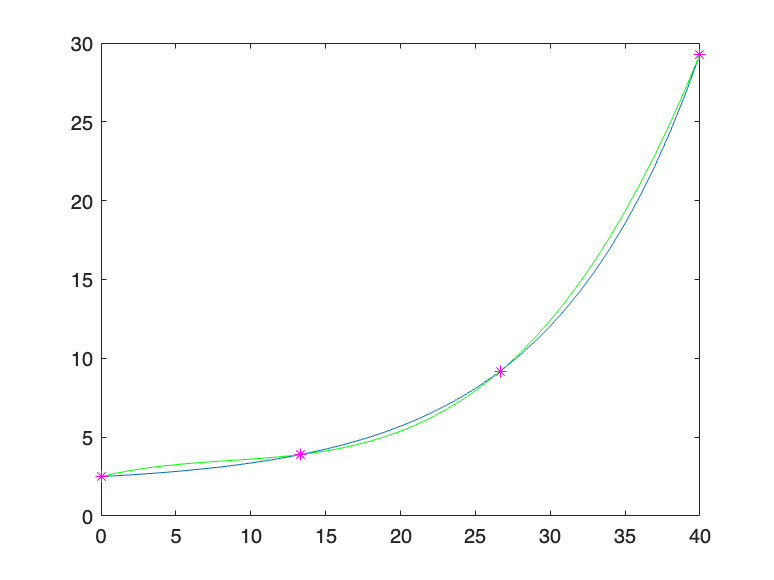

x = linspace(0, 40, 4)';
y = 0.5 * exp(0.1 * x) + 2;


xx = 0:1:40;
yy3_lagrange = Lagrange(x, y, xx);

plot(xx, yy, '-')
hold on
plot(xx, yy3_lagrange, 'g-',x , y, 'm*')
hold off